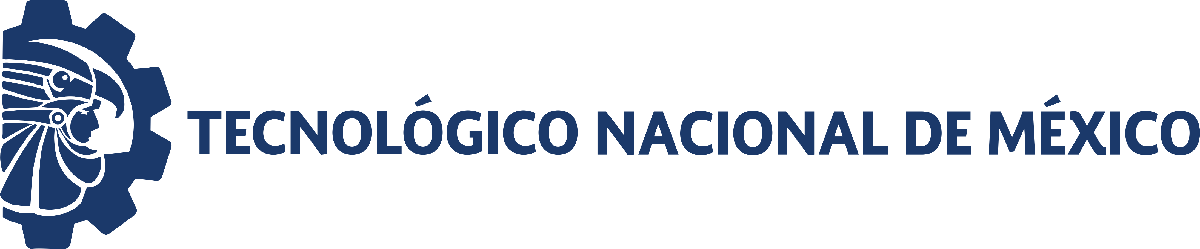                                 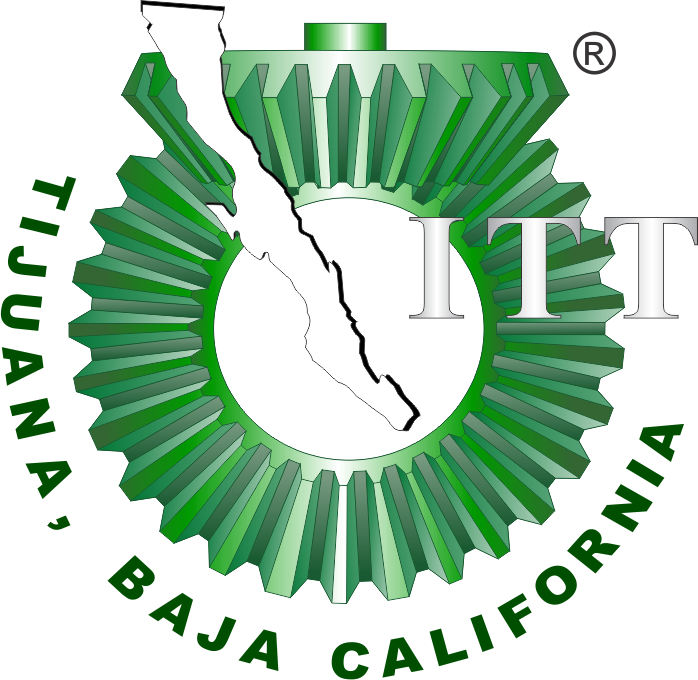

# Práctica 4: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

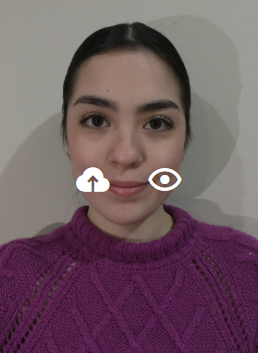S

Nombre del alumno: Celia Lizette Hernandez Ruiz

Número de control: 22210415

Correo institucional: L22210415@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '15'; 
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
Controlador = 'PI'; 

## Rendimiento del controlador

kP=Rr/Re

kl= 1/ReCr

kD=RrCe

Settling time= 0.0883

Overshoot= 0%

Peak=  1

## Lazo Abierto

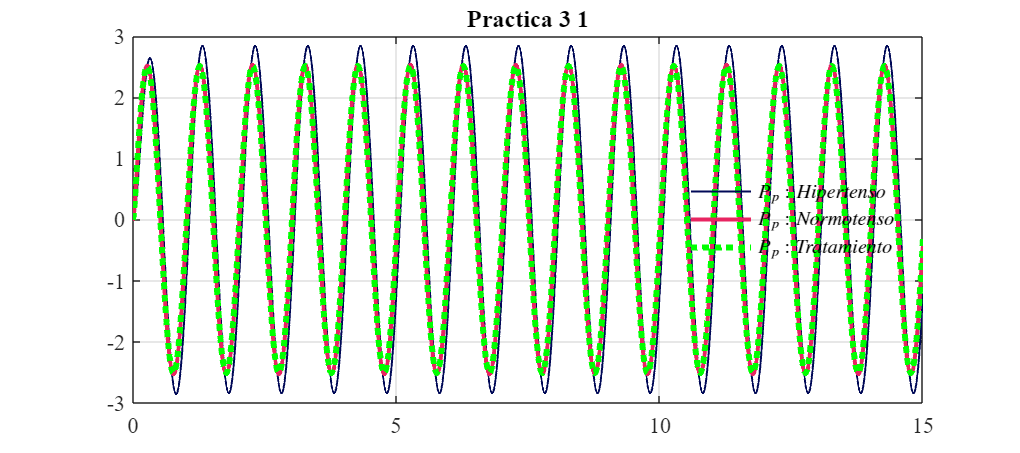

file = 'LAHernandez22210415';
open_system(file);
x = sim(file, parameters);
opt = 1;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt)

## Hipertenso

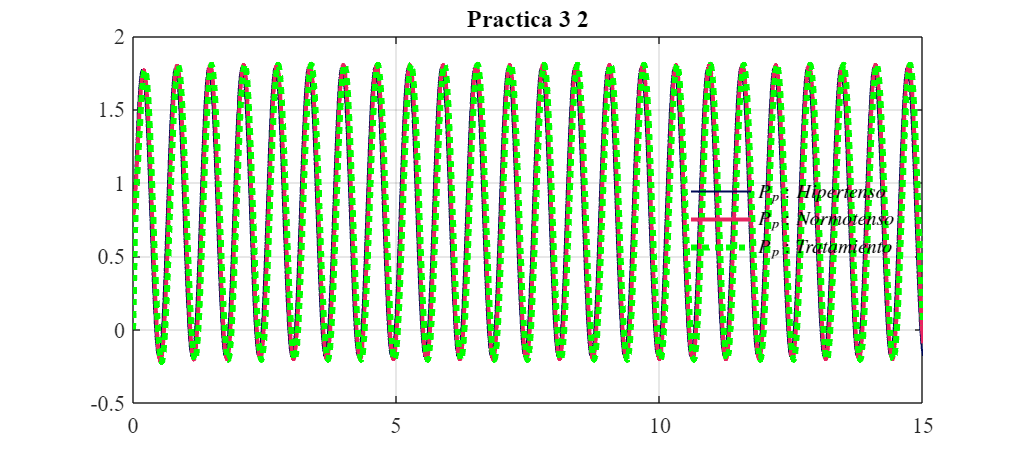

file = 'HHernandez22210415';
open_system(file);
x = sim(file, parameters);
opt = 2;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt)

## Hipotenso

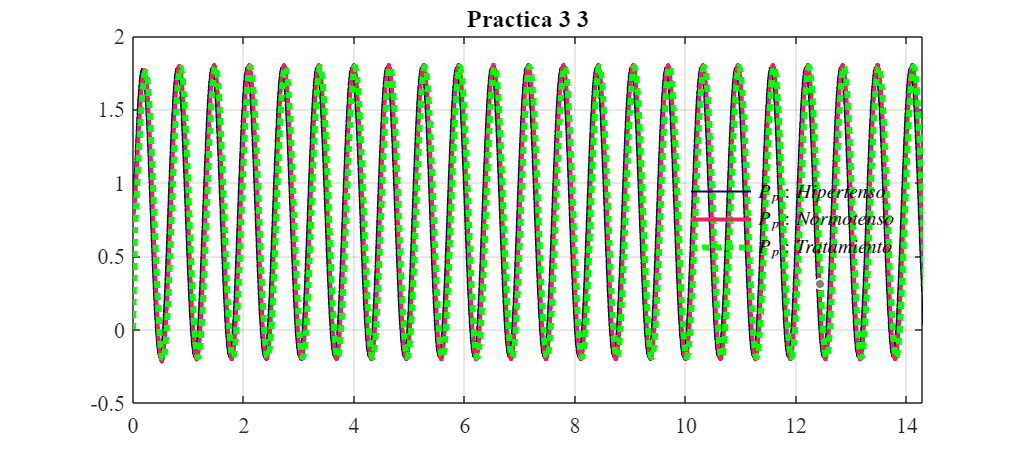

file = 'ZHernandez22210415';
open_system(file);
x = sim(file, parameters);
opt = 3;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt)

## Funcion:Respuesta a las señales

function plotsignals(t, Ppx, Ppy, Ppz, opt)
    set(figure(), 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 18, 8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    
    red = [232/255, 37/255, 97/255];
    blueR = [0, 9/255, 87/255];
    green = [0, 255/255, 0];
    
    hold on; grid on; box on;
    
    plot(t, Ppx, 'LineWidth', 1, 'Color', blueR);      % Hipetenso
    plot(t, Ppy, 'LineWidth', 2, 'Color', red);    % Normotenso
    plot(t, Ppz, ':', 'LineWidth', 3, 'Color', green); % Tratamiento
    
    title(['Practica 3 ' num2str(opt)]);
    
    L = legend('$P_{p}:Hipertenso$', ...
               '$P_{p}:Normotenso$', ...
               '$P_{p}:Tratamiento$');
    set(L, 'Interpreter', 'Latex', 'Location', 'Best', 'Box', 'off');
end